# Scenario Comparison Plots – Live Script

This Live Script visualises key macro‑economic and energy indicators for multiple policy scenarios. It reads pre‑computed scenario output tables (CSV) and produces indexed or percentage plots for a 25‑year horizon. 

Christoph Schult

## House‑keeping

clearvars
close all
clc

addpath('C:\dynare\6.1\matlab')   % ‑‑ adjust if necessary
load('structScenarioResultsssp185.mat')

% Scenario meta‑data
casScenarios = {'Baseline', 'NZ', 'NZ_constInt', 'NZ_constEE', 'NZ_constEEInt'};
caslegendentries = {'PDP8', 'NZ','NZ with constant emission efficiency', 'NZ with constant energy productivity', 'NZ with constant emission and energy efficiency'};
casLinetypes = {'-', '+-', '-.', '-o', '-^'};

% casScenarios      = {'Baseline', 'NZ'};              % add more if available
% caslegendentries  = {'PDP8', 'NZ'};                  % legend labels
% casLinetypes      = {'-', '+-'};                     % line styles / markers

% Read scenario CSV dumps -------------------------------------------------
dsall = struct();
for iscen = 1:numel(casScenarios)
    sScen              = char(casScenarios(iscen));
    filename           = ['ExcelFiles/Output/ssp185' sScen '.csv'];
    dsall.(sScen)      = readtable(filename);
end

Tplot = 25;           % number of years to display (starting from first row)

## Helper function (inline)

normalize = @(x) x ./ x(1) * 100;   % index to 100 in first period

## 1. Emissions

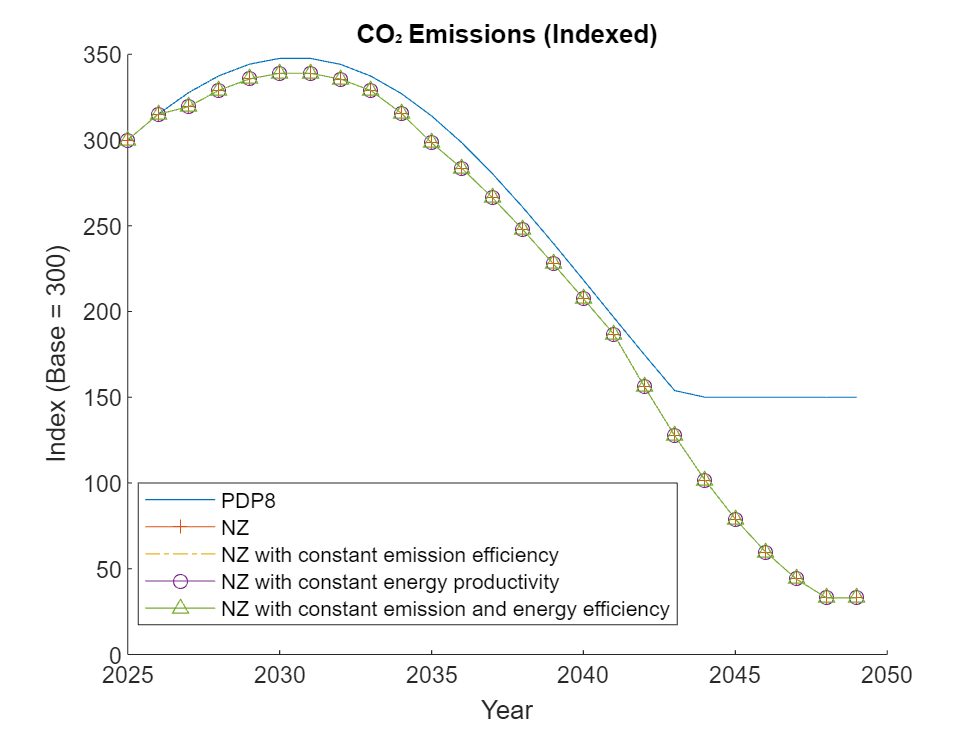

figure('Name','Emissions'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    plot(ds.Year(1:Tplot), ds.E_1(1:Tplot) ./ ds.E_1(1) * 300, casLinetypes{iscen});
end
xlabel('Year'); ylabel('Index (Base = 300)'); title('CO₂ Emissions (Indexed)'); legend(caslegendentries, 'Location', 'best'); hold off

## 2. Energy Productivity

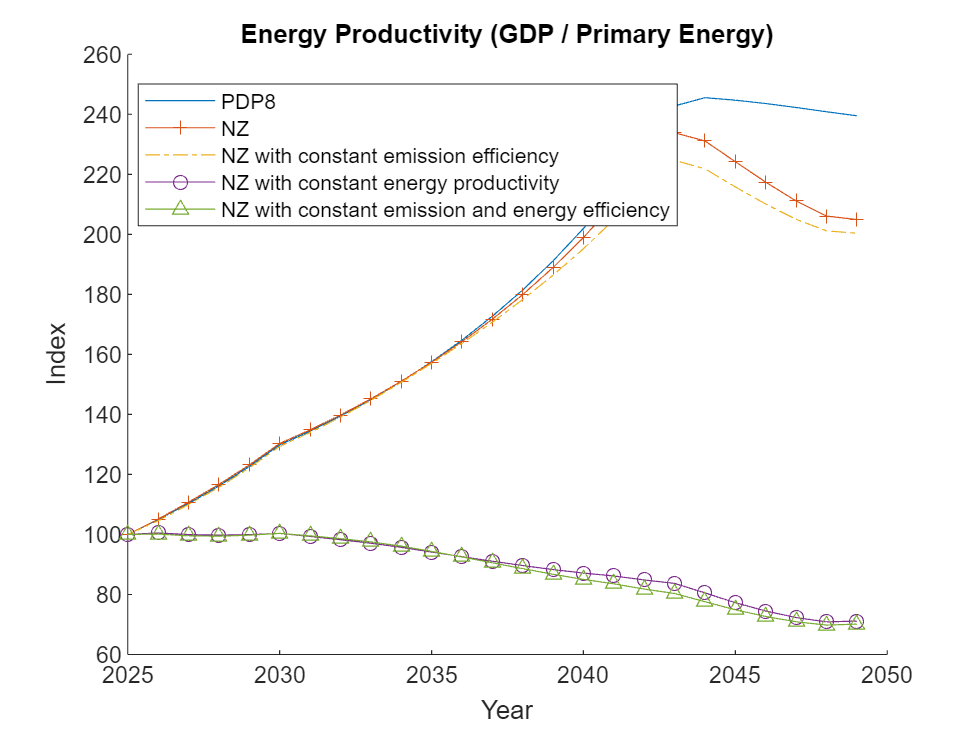

figure('Name','Energy productivity'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    prod = ds.Y_1 ./ (ds.Q_D_2_1 + ds.Q_D_3_1);
    plot(ds.Year(1:Tplot), normalize(prod(1:Tplot)), casLinetypes{iscen});
end
xlabel('Year'); ylabel('Index'); title('Energy Productivity (GDP / Primary Energy)'); legend(caslegendentries, 'Location', 'best'); hold off

## 3. Cap‑and‑Trade Revenues

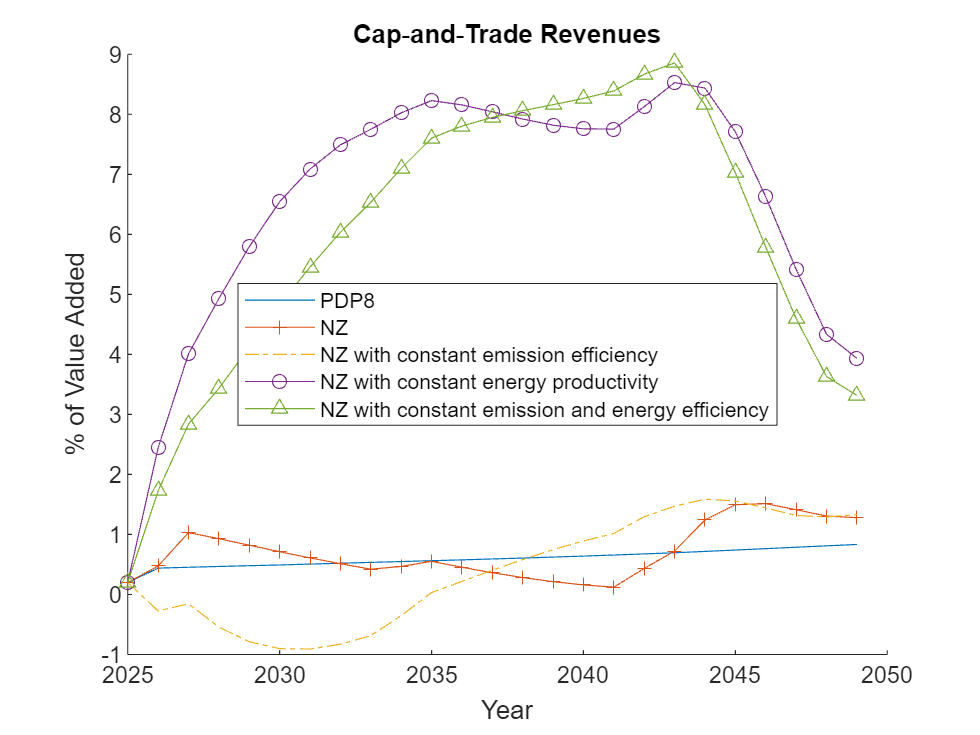

figure('Name','Cap and Trade Revenues'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    rev = ds.PE_1 .* ds.E_1 ./ (ds.Q_1 - ds.Q_I_1) * 100;   % share of VA
    plot(ds.Year(1:Tplot), rev(1:Tplot), casLinetypes{iscen});
end
xlabel('Year'); ylabel('% of Value Added'); title('Cap‑and‑Trade Revenues'); legend(caslegendentries, 'Location', 'best'); hold off

## 4. GDP Growth

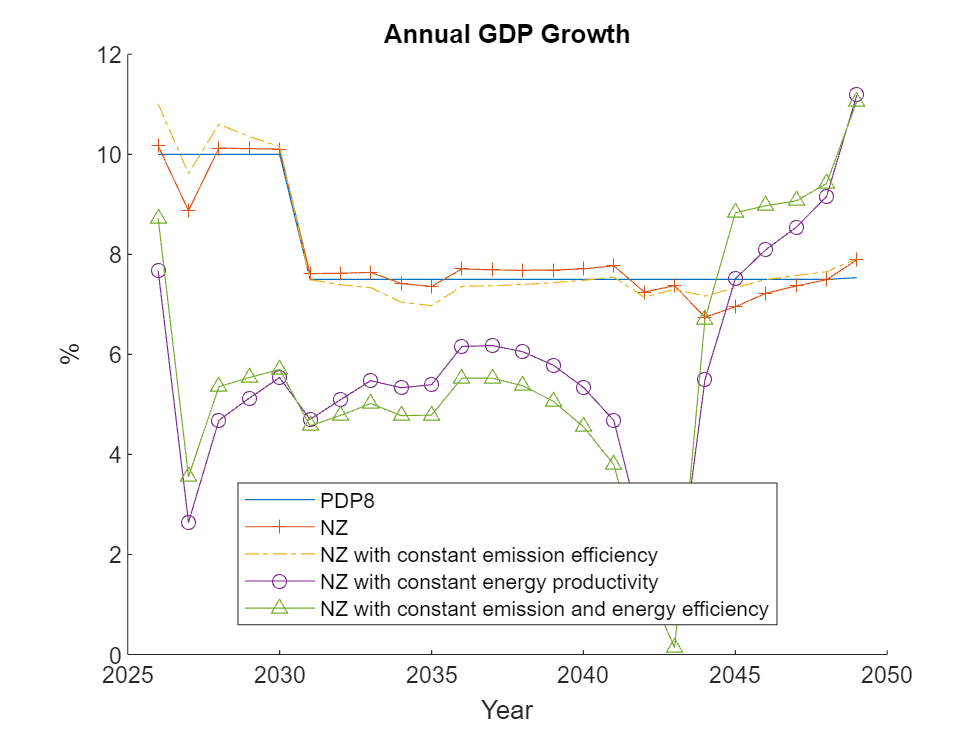

figure('Name','GDP Growth'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    gdp_growth = (ds.Y_1(2:Tplot) ./ ds.Y_1(1:Tplot-1) - 1) * 100;
    plot(ds.Year(2:Tplot), gdp_growth, casLinetypes{iscen});
end
xlabel('Year'); ylabel('%'); title('Annual GDP Growth'); legend(caslegendentries, 'Location', 'best'); hold off

## 5. Renewable Energy Share

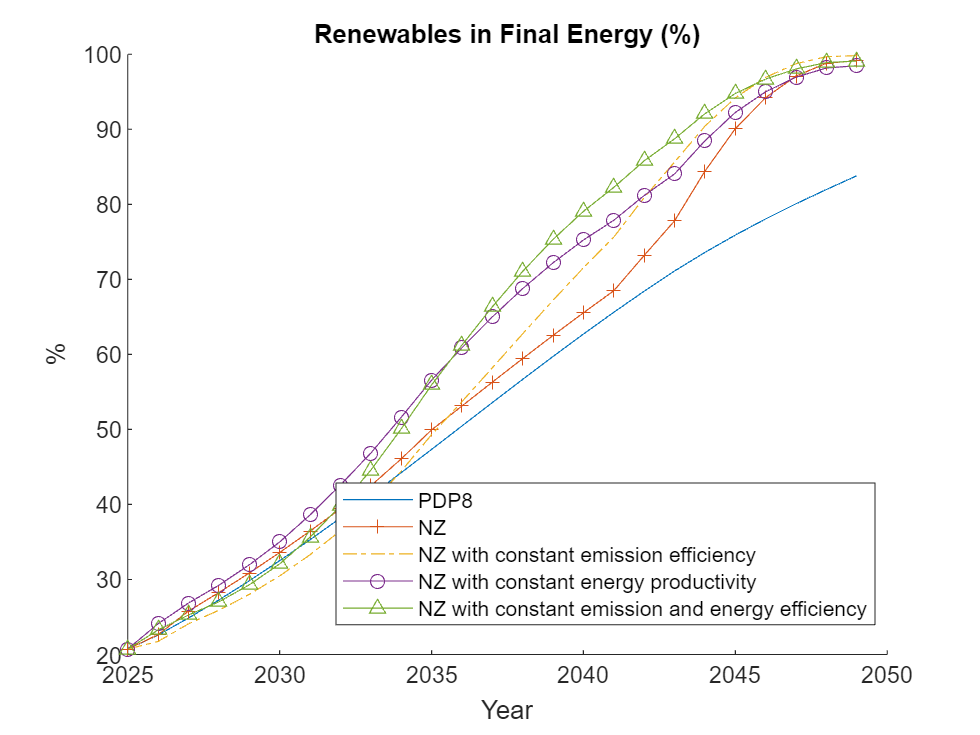

figure('Name','Renewable Energy Share'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    res_share = ds.Q_D_3_1 ./ (ds.Q_D_2_1 + ds.Q_D_3_1) * 100;
    plot(ds.Year(1:Tplot), res_share(1:Tplot), casLinetypes{iscen});
end
xlabel('Year'); ylabel('%'); title('Renewables in Final Energy (%)'); legend(caslegendentries, 'Location', 'best'); hold off

## 6. Emission Intensity

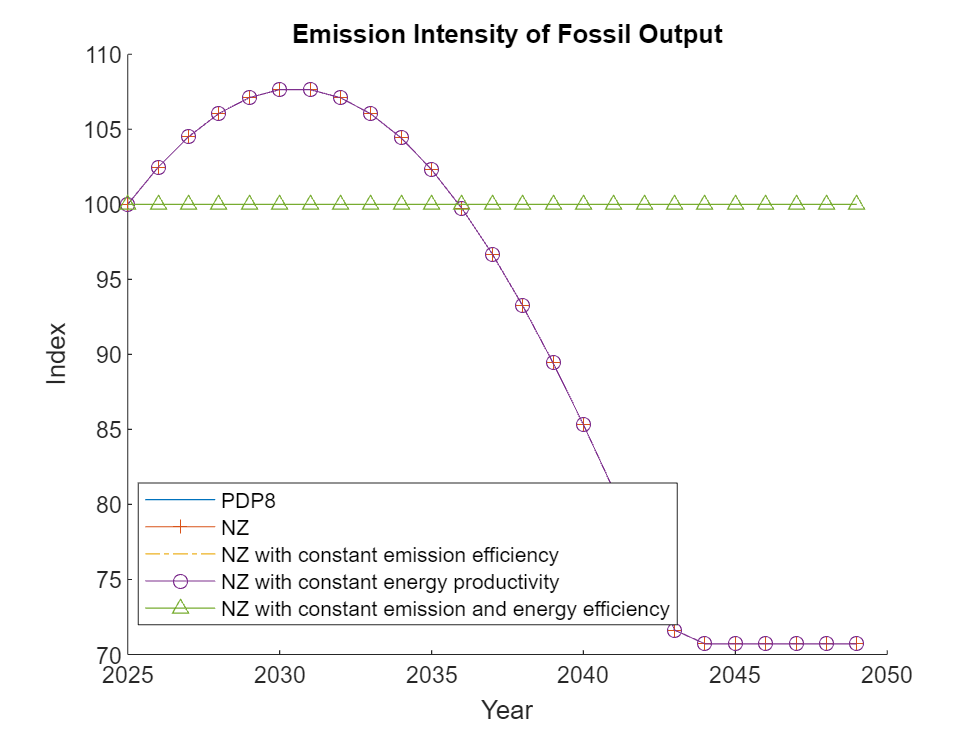

figure('Name','Emission Intensity'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    plot(ds.Year(1:Tplot), normalize(ds.kappaE_2_1(1:Tplot)), casLinetypes{iscen});
end
xlabel('Year'); ylabel('Index'); title('Emission Intensity of Fossil Output'); legend(caslegendentries, 'Location', 'best'); hold off

## 7. Energy Efficiency (Economy‑wide)

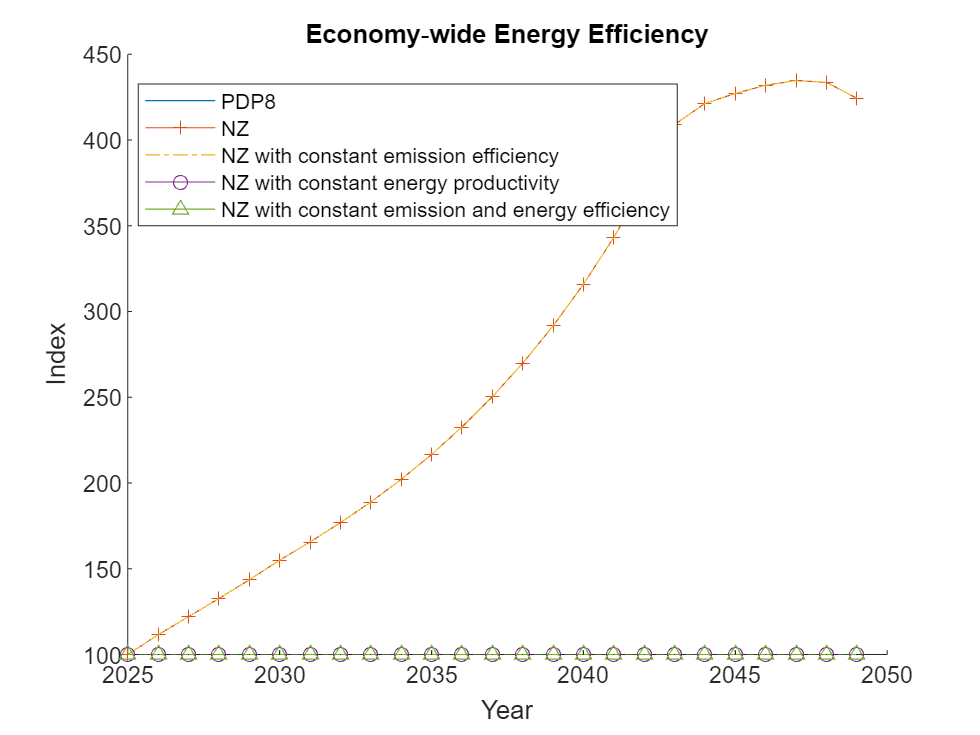

figure('Name','Energy efficiency'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    plot(ds.Year(1:Tplot), normalize(ds.EE_1(1:Tplot)), casLinetypes{iscen});
end
xlabel('Year'); ylabel('Index'); title('Economy‑wide Energy Efficiency'); legend(caslegendentries, 'Location', 'best'); hold off

## 8. Emission Price

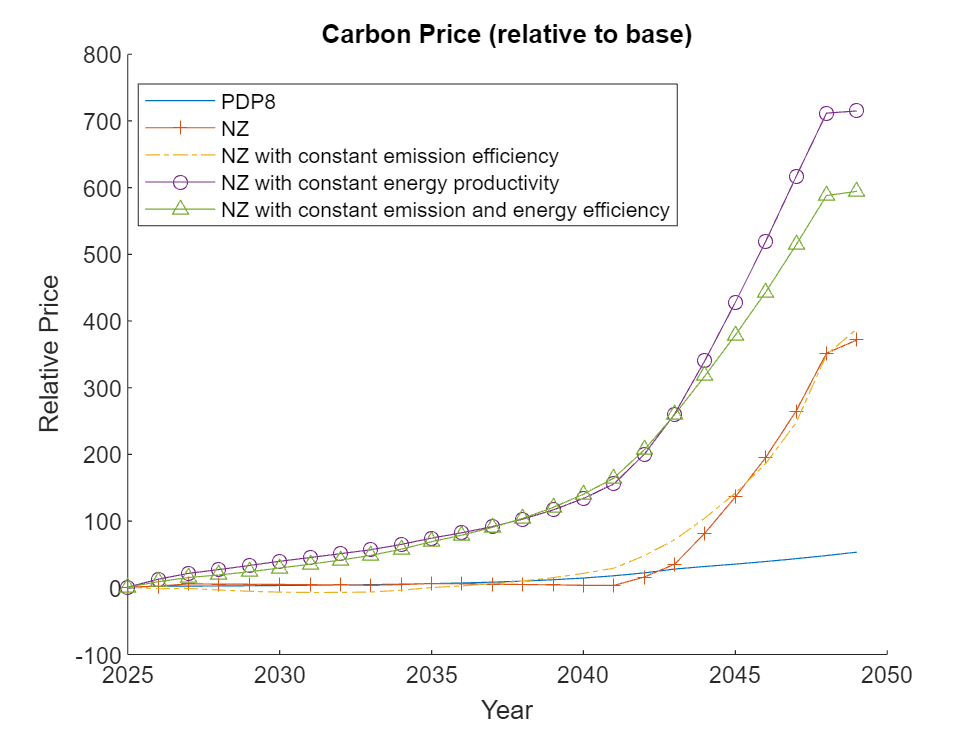

figure('Name','Emission price'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    plot(ds.Year(1:Tplot), ds.PE_1(1:Tplot) ./ ds.PE_1(1), casLinetypes{iscen});
end
xlabel('Year'); ylabel('Relative Price'); title('Carbon Price (relative to base)'); legend(caslegendentries, 'Location', 'best'); hold off

## 9. Investment in Renewables

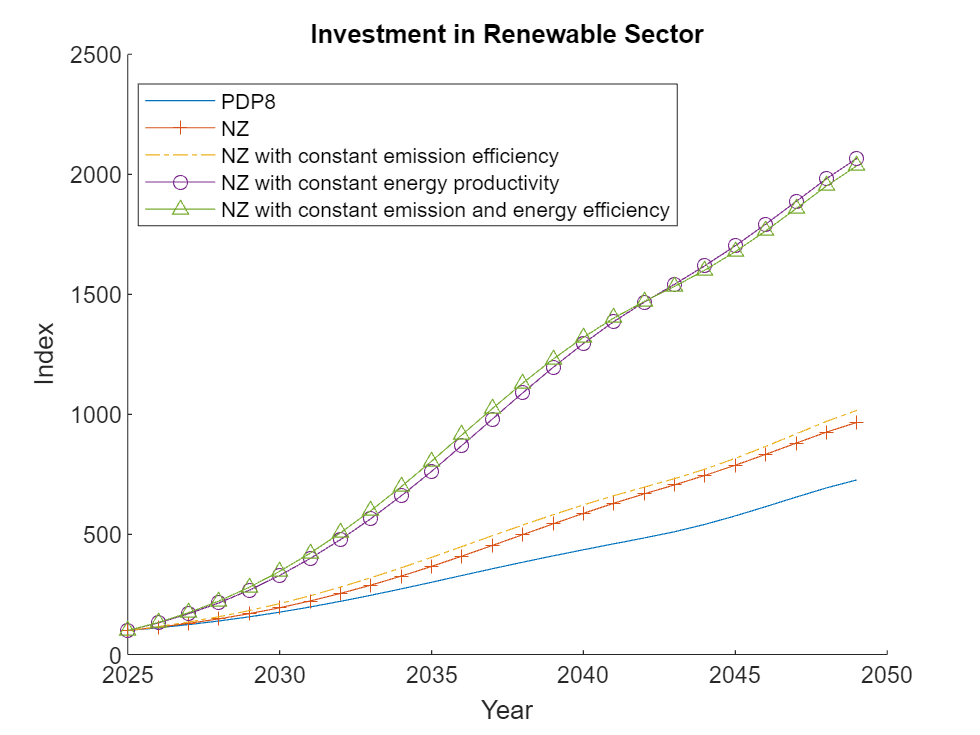

figure('Name','Investments – Renewables'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    plot(ds.Year(1:Tplot), normalize(ds.I_3_1(1:Tplot)), casLinetypes{iscen});
end
xlabel('Year'); ylabel('Index'); title('Investment in Renewable Sector'); legend(caslegendentries, 'Location', 'best'); hold off

## 10. Capital Stock – Renewables

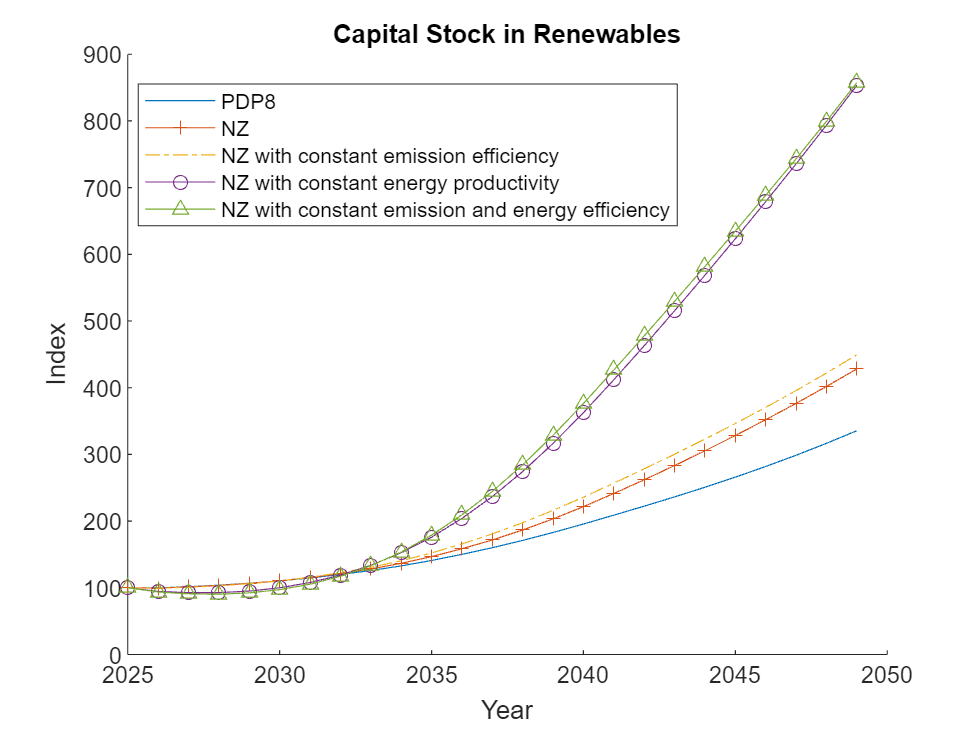

figure('Name','Capital – Renewables'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    plot(ds.Year(1:Tplot), normalize(ds.K_3_1(1:Tplot)), casLinetypes{iscen});
end
xlabel('Year'); ylabel('Index'); title('Capital Stock in Renewables'); legend(caslegendentries, 'Location', 'best'); hold off

## 11. Investment in Fossil

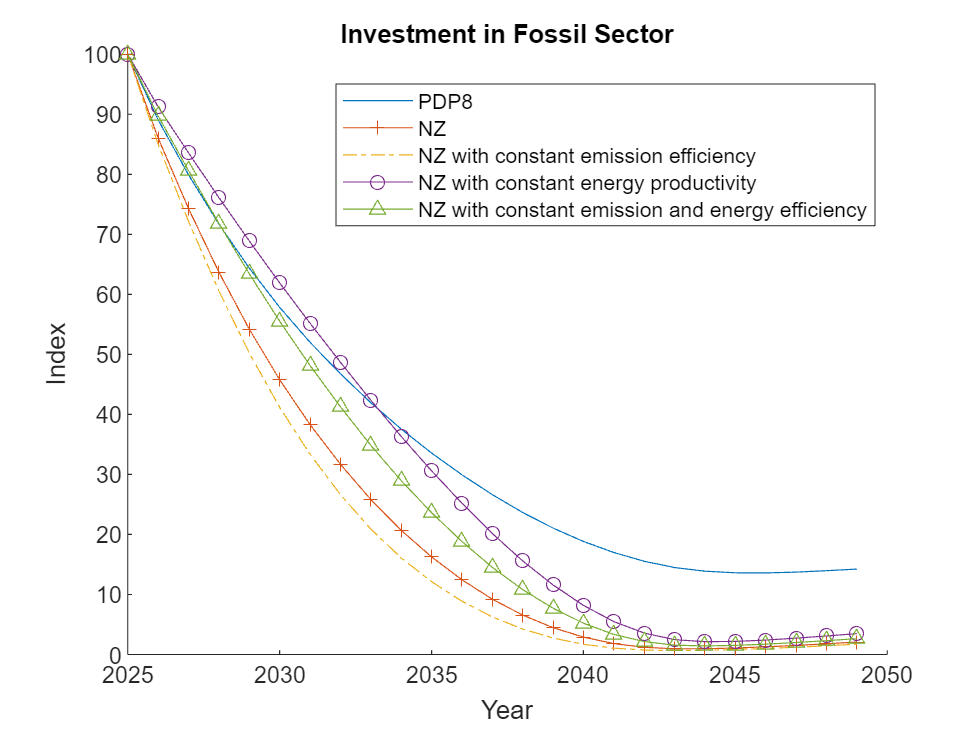

figure('Name','Investments – Fossil'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    plot(ds.Year(1:Tplot), normalize(ds.I_2_1(1:Tplot)), casLinetypes{iscen});
end
xlabel('Year'); ylabel('Index'); title('Investment in Fossil Sector'); legend(caslegendentries, 'Location', 'best'); hold off

## 12. Capital Stock – Fossil

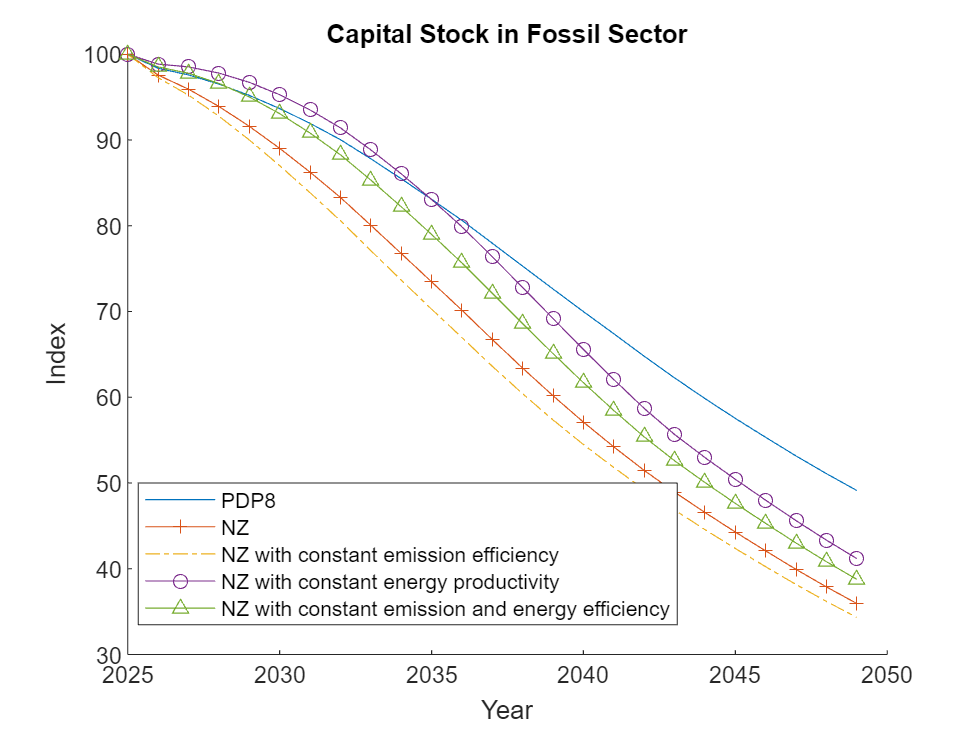

figure('Name','Capital – Fossil'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    plot(ds.Year(1:Tplot), normalize(ds.K_2_1(1:Tplot)), casLinetypes{iscen});
end
xlabel('Year'); ylabel('Index'); title('Capital Stock in Fossil Sector'); legend(caslegendentries, 'Location', 'best'); hold off

## 13. Capital / Value‑Added Ratio (Fossil)

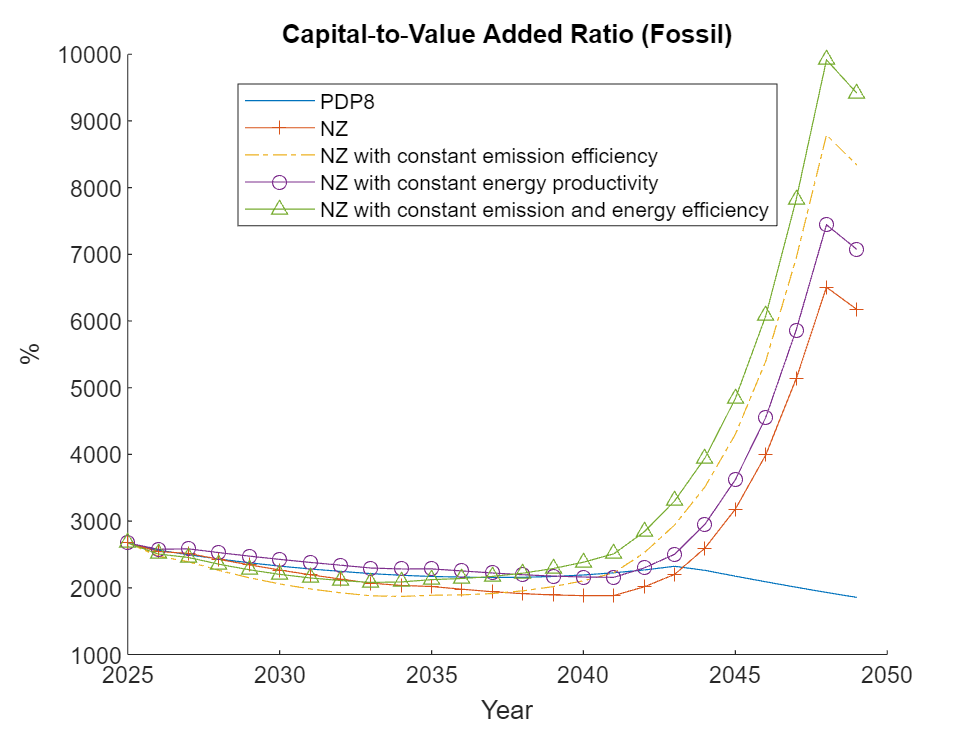

figure('Name','Capital‑to‑Value Added – Fossil'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    ratio = ds.K_2_1 ./ ds.Q_2_1 * 100;   % % of VA
    plot(ds.Year(1:Tplot), ratio(1:Tplot), casLinetypes{iscen});
end
xlabel('Year'); ylabel('%'); title('Capital‑to‑Value Added Ratio (Fossil)'); legend(caslegendentries, 'Location', 'best'); hold off

## 14. Employment – Fossil Sector

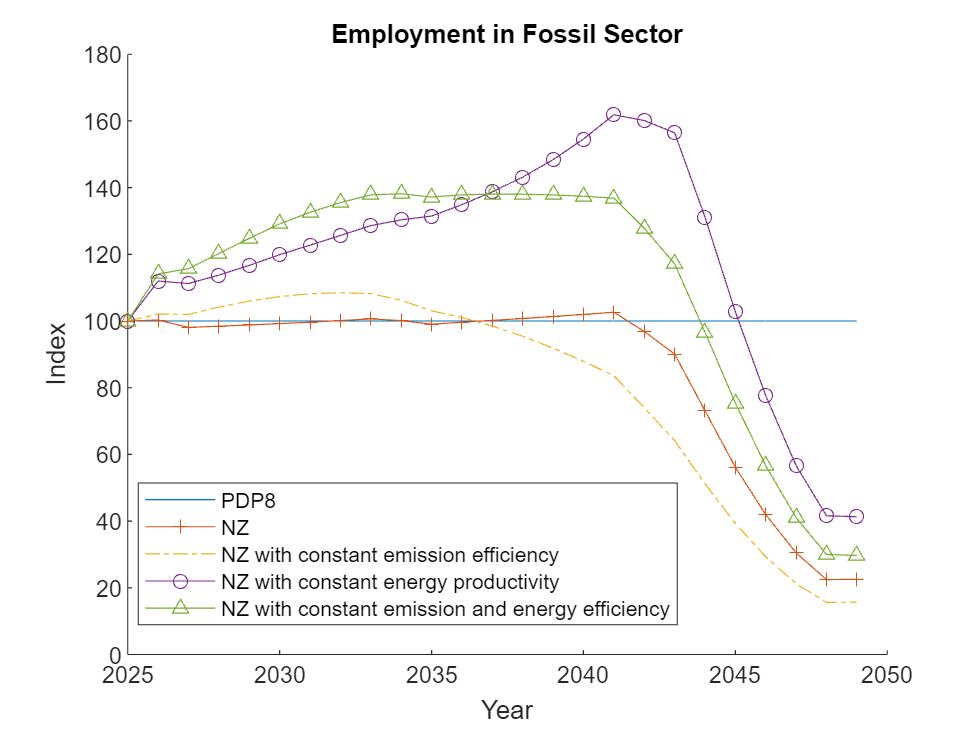

figure('Name','Employment – Fossil'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    plot(ds.Year(1:Tplot), normalize(ds.N_2_1(1:Tplot)), casLinetypes{iscen});
end
xlabel('Year'); ylabel('Index'); title('Employment in Fossil Sector'); legend(caslegendentries, 'Location', 'best'); hold off

## 15. Employment – Renewable Sector

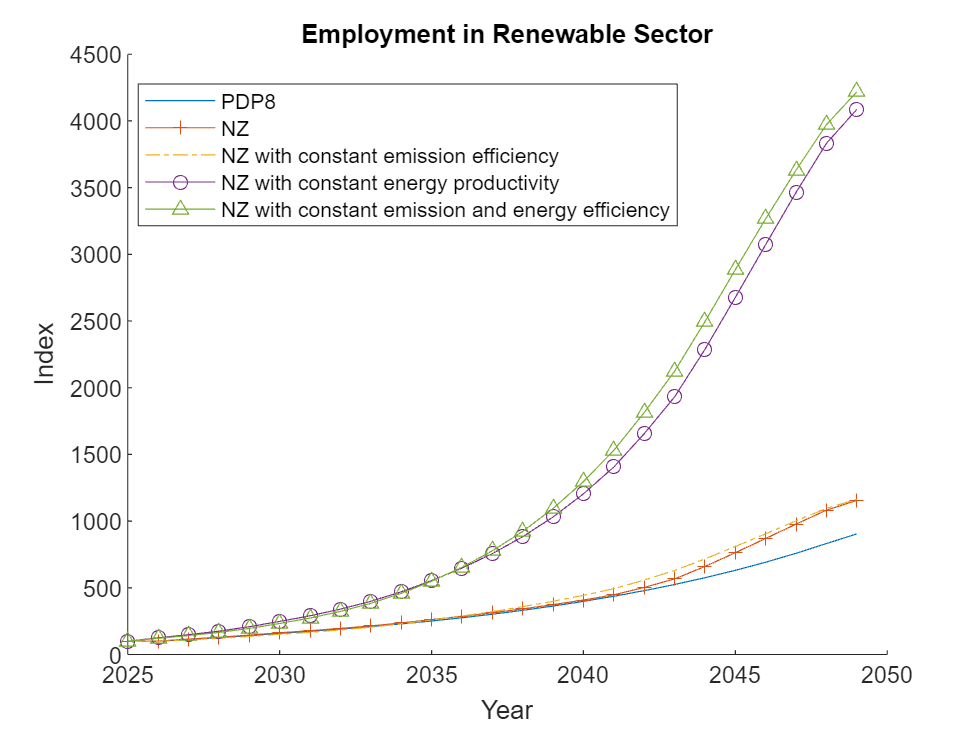

figure('Name','Employment – Renewables'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    plot(ds.Year(1:Tplot), normalize(ds.N_3_1(1:Tplot)), casLinetypes{iscen});
end
xlabel('Year'); ylabel('Index'); title('Employment in Renewable Sector'); legend(caslegendentries, 'Location', 'best'); hold off

## 16. Energy Output – Renewables (Index)

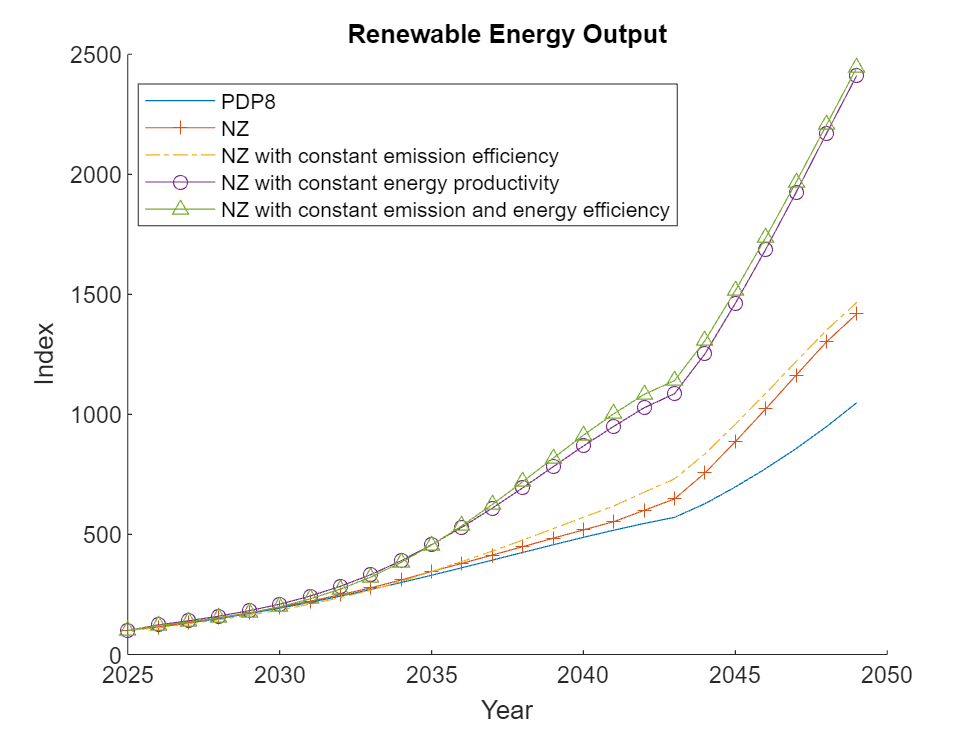

figure('Name','Energy Output – Renewables'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    plot(ds.Year(1:Tplot), normalize(ds.Q_3_1(1:Tplot)), casLinetypes{iscen});
end
xlabel('Year'); ylabel('Index'); title('Renewable Energy Output'); legend(caslegendentries, 'Location', 'best'); hold off

## 17. Energy Efficiency (kappaE₂₁ – absolute)

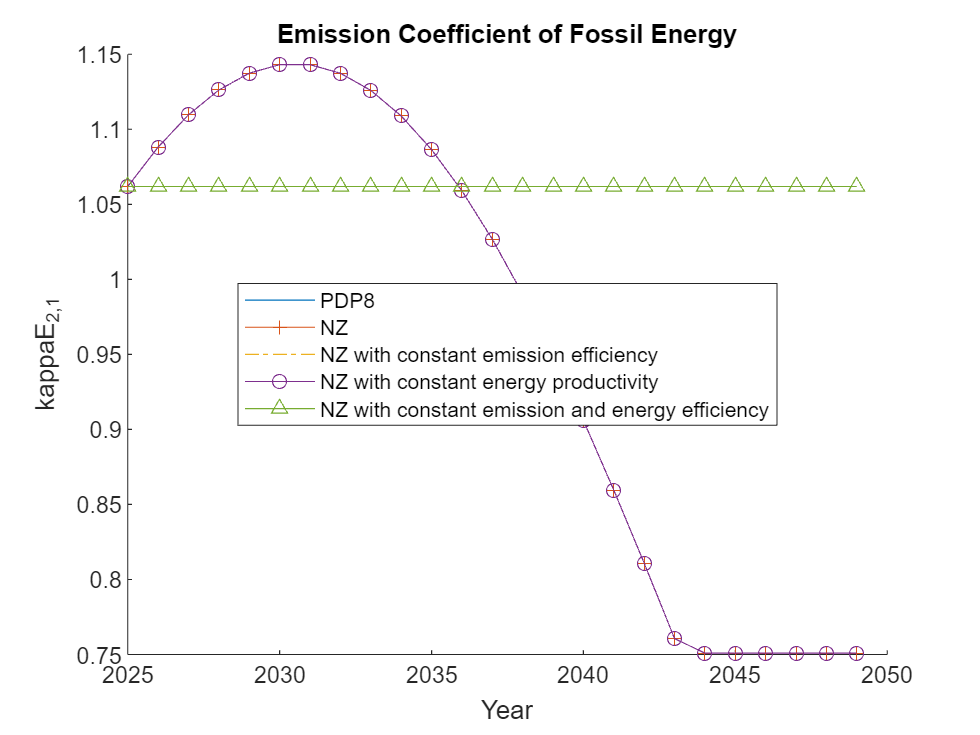

figure('Name','Energy Efficiency – kappaE'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    plot(ds.Year(1:Tplot), ds.kappaE_2_1(1:Tplot), casLinetypes{iscen});
end
xlabel('Year'); ylabel('kappaE_{2,1}'); title('Emission Coefficient of Fossil Energy'); legend(caslegendentries, 'Location', 'best'); hold off

## 18. Fossil Energy Production

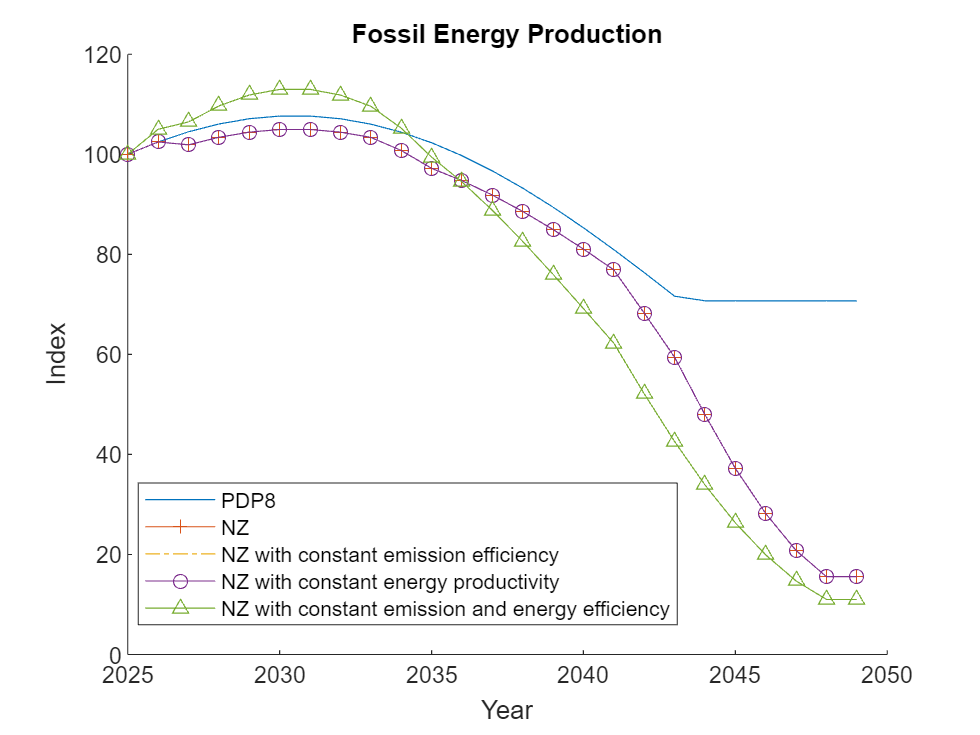

figure('Name','Fossil Energy Production'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    plot(ds.Year(1:Tplot), normalize(ds.Q_2_1(1:Tplot)), casLinetypes{iscen});
end
xlabel('Year'); ylabel('Index'); title('Fossil Energy Production'); legend(caslegendentries, 'Location', 'best'); hold off

## 19. Renewable Energy Production

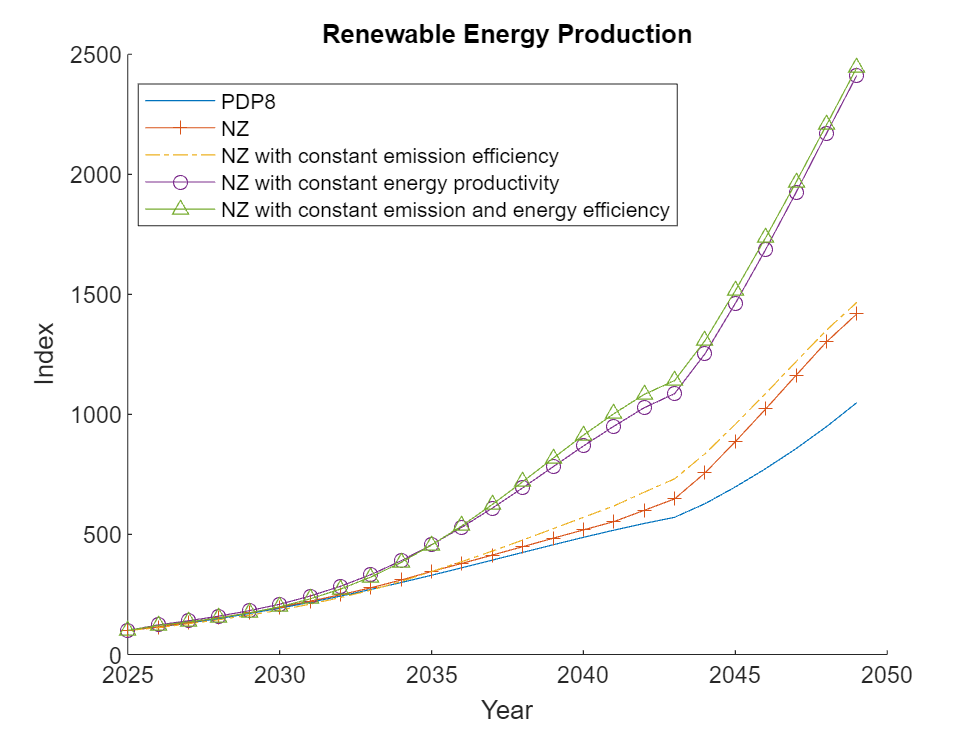

figure('Name','Renewable Energy Production'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    plot(ds.Year(1:Tplot), normalize(ds.Q_3_1(1:Tplot)), casLinetypes{iscen});
end
xlabel('Year'); ylabel('Index'); title('Renewable Energy Production'); legend(caslegendentries, 'Location', 'best'); hold off

## 20. Fossil Energy Price (Value Added)

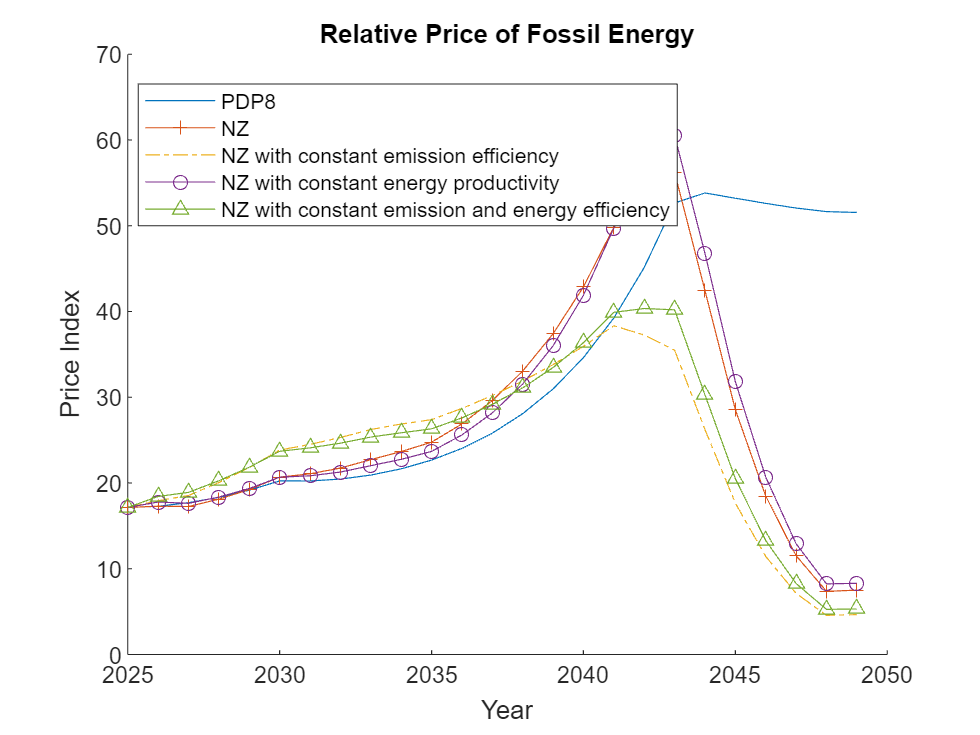

figure('Name','Fossil Energy Price – VA'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    plot(ds.Year(1:Tplot), ds.P_2_1(1:Tplot) * 100, casLinetypes{iscen});
end
xlabel('Year'); ylabel('Price Index'); title('Relative Price of Fossil Energy'); legend(caslegendentries, 'Location', 'best'); hold off

## 21. Sectoral Shares in Value Added

Agriculture

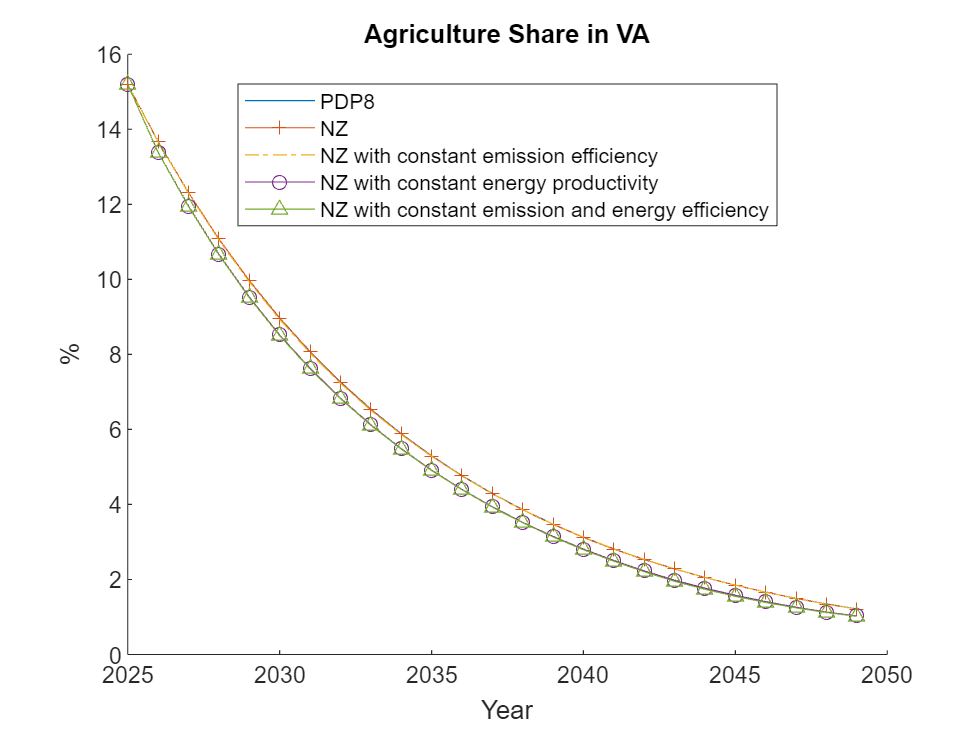

figure('Name','VA Share – Agriculture'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    shareAg = ds.P_1_1 .* ds.Y_1_1 ./ ds.Y_1 * 100;
    plot(ds.Year(1:Tplot), shareAg(1:Tplot), casLinetypes{iscen});
end
xlabel('Year'); ylabel('%'); title('Agriculture Share in VA'); legend(caslegendentries, 'Location', 'best'); hold off

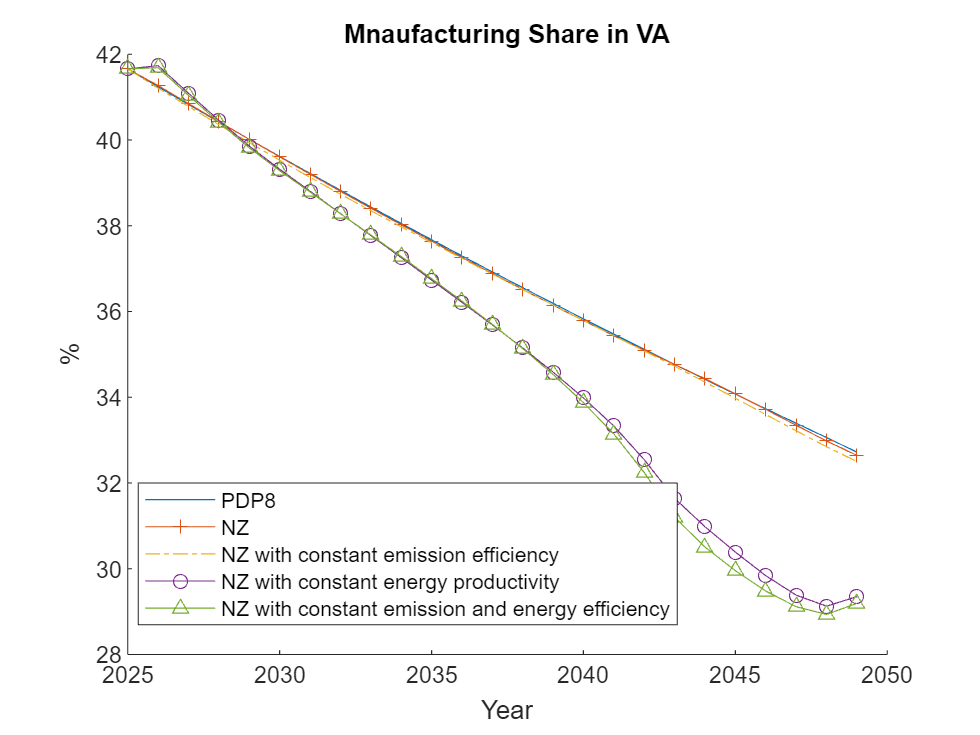


% Manufacturing
figure('Name','VA Share – Manufacturing'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    shareMan = ds.P_4_1 .* ds.Y_4_1 ./ ds.Y_1 * 100;
    plot(ds.Year(1:Tplot), shareMan(1:Tplot), casLinetypes{iscen});
end
xlabel('Year'); ylabel('%'); title('Mnaufacturing Share in VA'); legend(caslegendentries, 'Location', 'best'); hold off

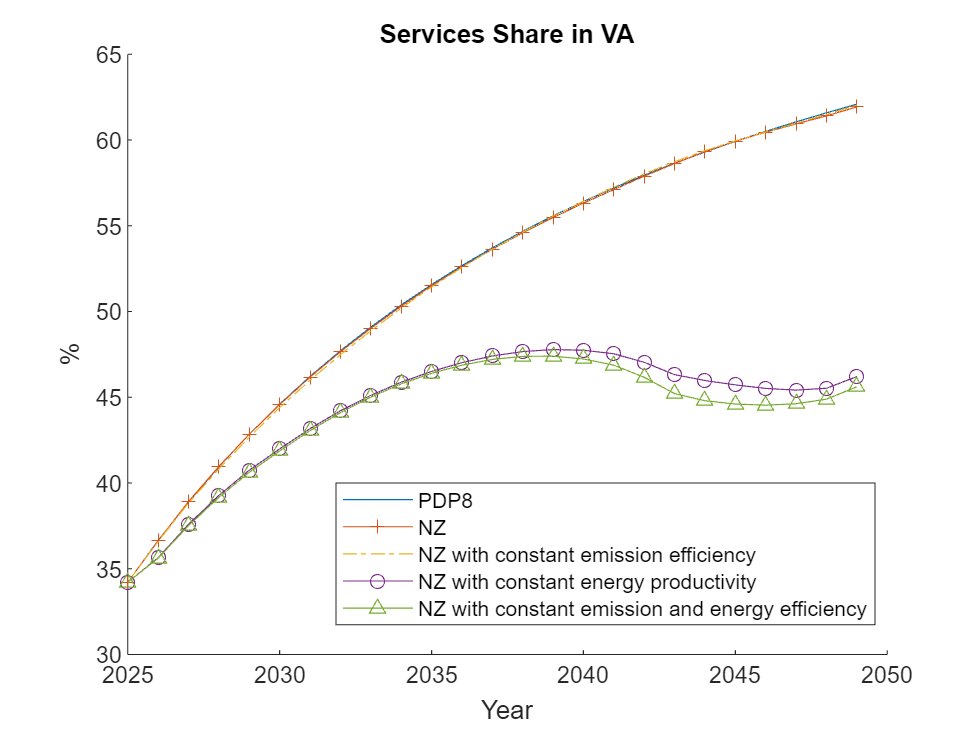

% Services
figure('Name','VA Share – Servies'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    shareMan = ds.P_5_1 .* ds.Y_5_1 ./ ds.Y_1 * 100;
    plot(ds.Year(1:Tplot), shareMan(1:Tplot), casLinetypes{iscen});
end
xlabel('Year'); ylabel('%'); title('Services Share in VA'); legend(caslegendentries, 'Location', 'best'); hold off

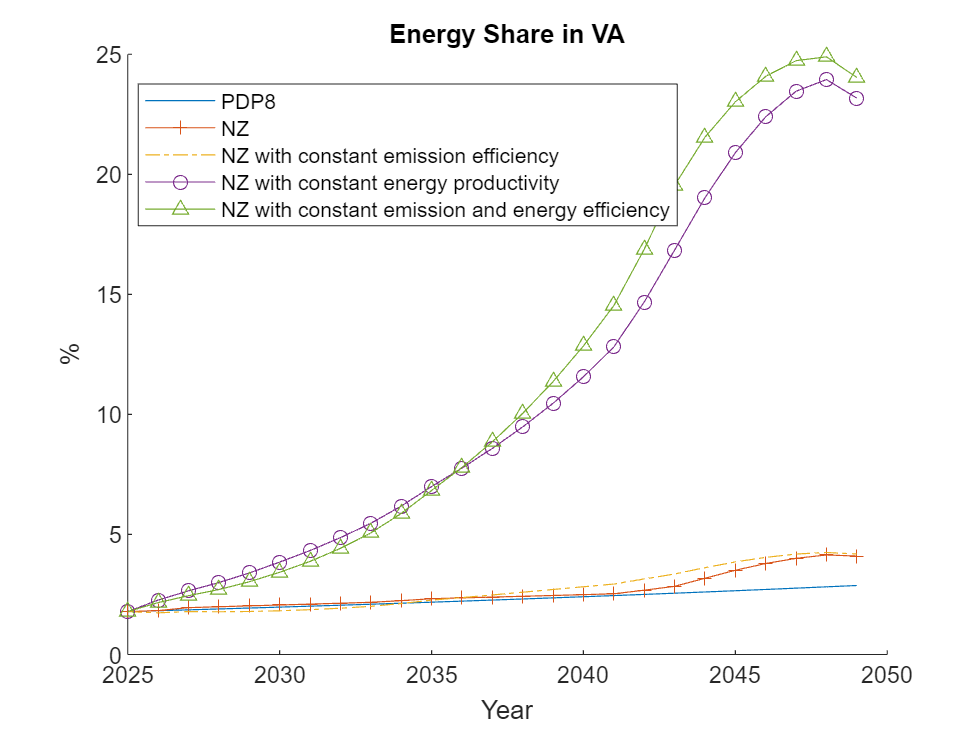


% Energy
figure('Name','VA Share - Energy'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    shareMan = ds.P_3_1 .* ds.Y_3_1 ./ ds.Y_1 * 100;
    plot(ds.Year(1:Tplot), shareMan(1:Tplot), casLinetypes{iscen});
end
xlabel('Year'); ylabel('%'); title('Energy Share in VA'); legend(caslegendentries, 'Location', 'best'); hold off